## **2.a.**

p = 10^-2;
bytes = 100;
bits = 8;

without_errors = nchoosek(bytes*bits, 0) * (1-p)^(bytes*bits);
without_errors_percentage = without_errors * 100

without_errors_percentage = 0.0322

## **2.b.**

p = 10^-3;
bytes = 1000;

one_error = nchoosek(bytes*bits, 1) * p * (1-p)^(bytes*bits - 1);
one_error_percentage = one_error * 100

one_error_percentage = 0.2676

## **2.c.**

p = 10^-4;
bytes = 200;

without_errors = nchoosek(bytes*bits, 0) * (1-p)^(bytes*bits);
one_more_errors = 1 - without_errors

one_more_errors = 0.1479

## **2.d.**

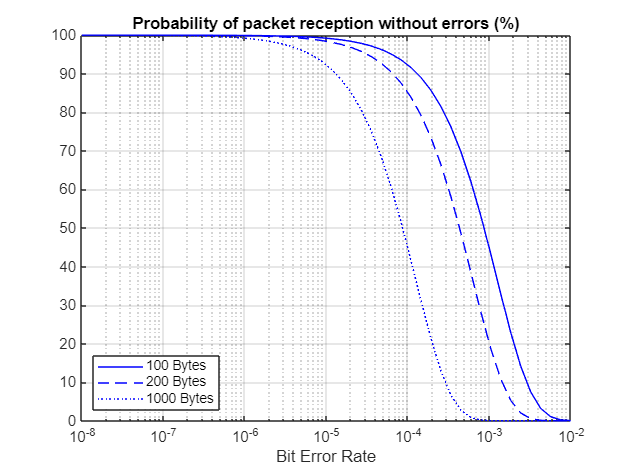

x = logspace(-8, -2);

bytes = 100;
without_errors100 = nchoosek(bytes*bits, 0) .* (1-x).^(bytes*bits);

bytes = 200;
without_errors200 = nchoosek(bytes*bits, 0) .* (1-x).^(bytes*bits);

bytes = 1000;
without_errors1000 = nchoosek(bytes*bits, 0) .* (1-x).^(bytes*bits);

figure;
semilogx(x, without_errors100*100, 'b-', x, without_errors200*100, 'b--', x, without_errors1000*100, 'b:');
xlabel('Bit Error Rate');
title('Probability of packet reception without errors (%)');
legend('100 Bytes','200 Bytes','1000 Bytes', 'location','southwest');
grid on;

## **2.e.**

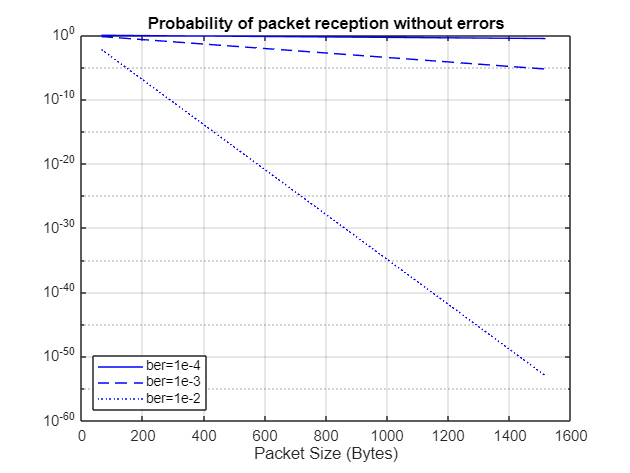

packet_sizes = linspace(64*bits, 1518*bits);

without_errors4 = (1-10^-4).^packet_sizes;
without_errors3 = (1-10^-3).^packet_sizes;
without_errors2 = (1-10^-2).^packet_sizes;

figure;
x = linspace(64, 1518);
semilogy(x, without_errors4, 'b-', x, without_errors3, 'b--', x, without_errors2, 'b:');
xlabel('Packet Size (Bytes)');
title('Probability of packet reception without errors');
legend('ber=1e-4','ber=1e-3','ber=1e-2', 'location','southwest');
grid on;